# ROZWIĄZAYWANIE UKŁADÓW RÓWNAŃ LINIOWYCH

## Problem złożoności obliczeniowej i dokładności rozwiązania

Program przedstawiony poniżej realizuje obliczenia losowo generowanych układów równań za pomocą dwóch metod poznanych w dalszej części wykładu - rozkładu LU oraz QR. Wyświetlane są wykresy ilości czasu liczonego w taktach procesora od rozmiaru układu i użytej metody (jest to estymata złożoności obliczeniowej) oraz błędu rozwiązania. 

Układy generowane są w taki sposób, aby rozwiązanie zawsze było równe wektorowi jedynek. Można to uzyskać, jeżeli każdy element wektora ***b*** jest sumą współczynników w danym wierszu macierzy ***A***.

**UWAGA! **Ponieważ miarą naszej złożoności jest czas wykonania mierzony jako różnica w pomiar ten mogą wchodzić szumy, szczególnie spowodowane działaniem systemu operacyjnego - mierzony jest czas pracy procesora, który może zostać przełączony w inny wątek np. systemowy. 

**Dodatkowo należy pamiętać o naturze klasy złożoności i zależności między faktyczną złożonością a klasą  złożoności.**

Na rysunku wynikowym mamy:

- QR - złożoność czasowa/błąd dla pełnej metody QR wraz z przeprowadzeniem rozkładu

- LU  - złożoność czasowa/błąd dla pełnej metody LU wraz z przeprowadzeniem rozkładu

- Rozwiązanie - złożoność czasowa dla samego rozwiązania układu równań bez rozkładu

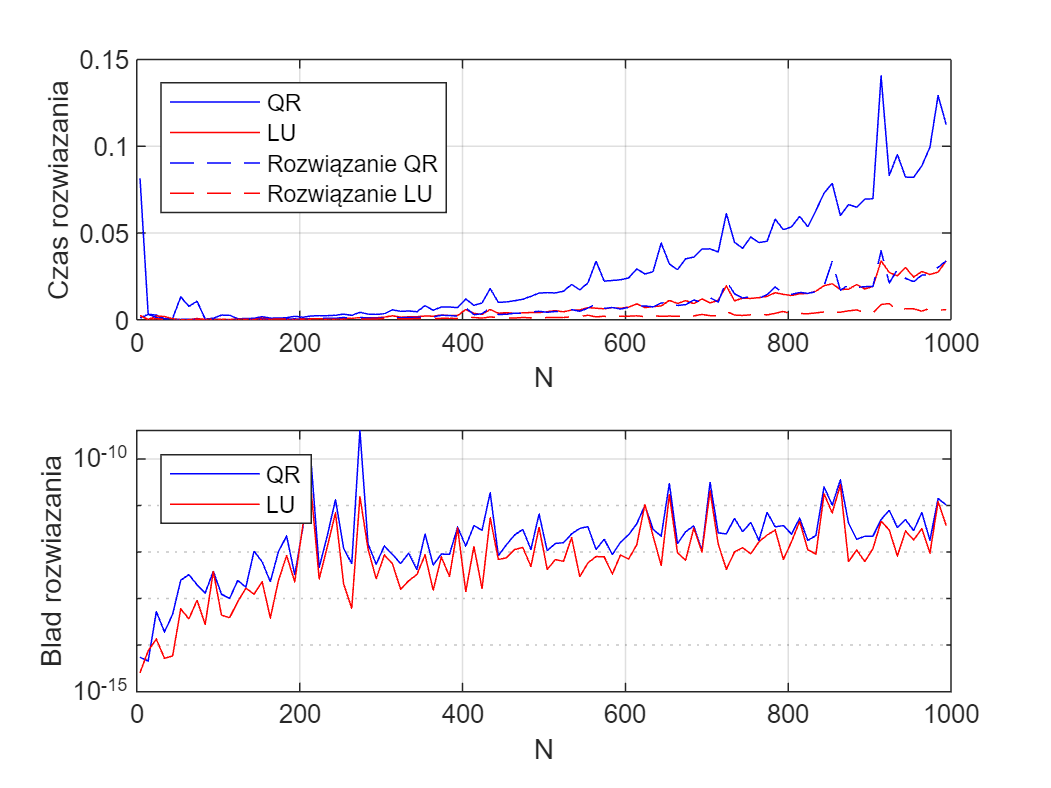

%Czyszczenie
clear all;
close all;
clc;

% Poniżej prowadzamy maksymalna ilość równań i krok z jakim ma być
% zwiększana ilość równań zaczynając od 4
Nmax=1000;
step=10;

bladQR=[];bladLU=[];
zlozonoscQR=[];zlozonoscLU=[];zlozonoscRozwQR=[];zlozonoscRozwLU=[];
N=[];maxNumCompThreads(1);

%Generujemy losowy układ równań o rozwiązaniu będącym wektorem samych
%jedynek
h = waitbar(0,'Rozwiazywanie...');
for i=[4:step:Nmax]
A=rand(i);
b=sum(A,2);
[timeAll, timeSimple, error]=solveUsingQRFactorization(A,b);
bladQR=[bladQR error];zlozonoscRozwQR=[zlozonoscRozwQR timeSimple];
zlozonoscQR=[zlozonoscQR timeAll];N=[N i];warning('off');
[timeAll, timeSimple, error]=solveUsingLUFactorization(A,b);
bladLU=[bladLU error];zlozonoscLU=[zlozonoscLU timeAll];zlozonoscRozwLU=[zlozonoscRozwLU timeSimple];

%Rysowanie

tiledlayout(2,1)
nexttile
plot(N,zlozonoscQR,'b',N,zlozonoscLU,'r',N,zlozonoscRozwQR,'--b',N,zlozonoscRozwLU,'--r');xlabel("N");ylabel("Czas rozwiazania");grid on; 
legend("QR", "LU","Rozwiązanie QR","Rozwiązanie LU",'Location','northwest');
nexttile
semilogy(N,abs(bladQR)+1e-16,'b',N,abs(bladLU)+1e-16,'r');xlabel("N");ylabel("Blad rozwiazania");grid on; legend("QR", "LU",'Location','northwest');
waitbar(i / Nmax);
end

close(h);warning('on');

 

## Wykorzystywane funkcje

function [timeAll, timeSimple, error]=solveUsingQRFactorization(A,b)

%Startujemy licznik czasu
time1 = tic;

%Rozkład QR
[Q,R]=qr(A);

%Startujemy licznik tylko obliczenia
time2 = tic;

%Rozwiązanie metodą QR w dwóch krokach zapisane w jednej linijce żeby
%prawidłowo mierzyć złożoność
x=R\Q.'*b;
% Rozpisane na dwie linijki byłoby y=Q'*b; x=R\y;

%Zakończenie liczenia czasu
time2end = toc(time2);
time1end = toc(time1);

%Obliczenie błędów zakładając, ze rozwiazaniem jest wektor jedynek
error=(norm(x - ones(numel(b),1)))/norm(ones(numel(b),1));

%Inne wartosci wyjściowe
timeAll=time1end;
timeSimple=time2end;
end

function [timeAll, timeSimple, error]=solveUsingLUFactorization(A,b)

%Startujemy licznik czasu
time1 = tic;

%Rozkład LU
%[L,U,P]=lu(A);
[L,U]=lu(A);

%Startujemy licznik tylko obliczenia
time2 = tic;

%Rozwiązanie metodą LU w dwóch krokach zapisane w jednej linijce żeby
%prawidłowo mierzyć złożoność
x = U\(L\b);
% Rozpisane na dwie linijki byłoby y = L\(P*b); x = U\y;

%Zakończenie liczenia czasu
time2end = toc(time2);
time1end = toc(time1);

%Obliczenie błędów zakłądając, ze rozwiazaniem jest wektor jedynek
error=(norm(x - ones(numel(b),1)))/norm(ones(numel(b),1));

%Inne wartosci wyjściowe
timeAll=time1end;
timeSimple=time2end;
end